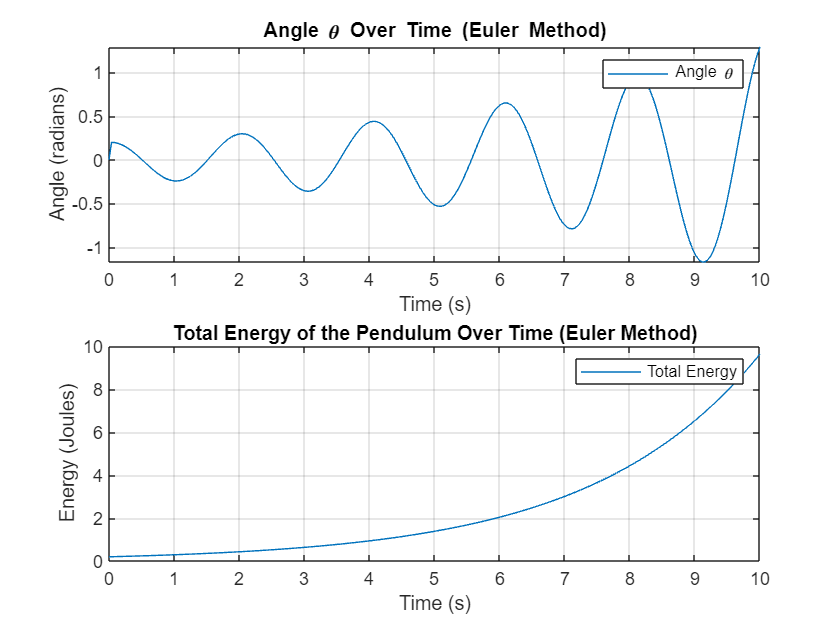

% Constants
g = 9.81; % acceleration due to gravity in m/s^2
length = 1.0; % length of pendulum in meters
mass = 1.0; % mass of pendulum in kg (cancels out in energy equation)
time_step = 0.04; % time step in seconds
total_time = 10.0; % total time for simulation in seconds
num_steps = total_time / time_step; % number of steps in the simulation

% Initial conditions
theta = 0.2; % initial angle in radians
omega = 0.0; % initial angular velocity in radians/s

% Arrays to hold time evolution
thetas = zeros(1, num_steps);  % Array to store the angle theta at each time step
omegas = zeros(1, num_steps);  % Array to store the angular velocity omega at each time step
energies = zeros(1, num_steps); % Array to store the total energy of the pendulum at each time step 
times = linspace(0, total_time, num_steps);  % Array to store the time points for the simulation

% Initial energy calculation
kinetic_energy = 0.5 * mass * (length * omega)^2;
potential_energy = mass * g * length * (1 - cos(theta));
energies(1) = kinetic_energy + potential_energy;

% Simulation using the Euler method
for i = 1:num_steps-1
    % Update angular velocity
    omega_new = omega - (g / length) * theta * time_step;
    % Update angle
    theta_new = theta + omega * time_step; % Note the use of omega, not omega_new
    
    % Store new values
    omega = omega_new;
    theta = theta_new;
    
    thetas(i+1) = theta;
    omegas(i+1) = omega;
    
    % Calculate total energy at this step using modified equation (3.8)
    kinetic_energy = 0.5 * mass * (length * omega)^2;
    potential_energy = mass * g * length * (1 - cos(theta));
    energies(i+1) = energies(i) + 0.5 * mass * g * (omega^2 + (g/length) * theta^2) * time_step^2;
end

% Plotting
figure;

% Subplot for angle theta over time
subplot(2, 1, 1);
plot(times, thetas, 'DisplayName', 'Angle \theta');
xlabel('Time (s)');
ylabel('Angle (radians)');
title('Angle \theta Over Time (Euler Method)');
legend;
grid on;

% Subplot for total energy over time
subplot(2, 1, 2);
plot(times, energies, 'DisplayName', 'Total Energy');
xlabel('Time (s)');
ylabel('Energy (Joules)');
title('Total Energy of the Pendulum Over Time (Euler Method)');
legend;
grid on;